## Load in the data

clear all
rng(42,"twister")
addpath(genpath('../'));
dataPath = "../../../data/smoothed_data/KE05_10.csv";
kernLen = 90;
dataTable = readtable(dataPath);
dates = dataTable.date(kernLen:end-kernLen);
ndvi = dataTable.ndvi(kernLen:end-kernLen);
precip = dataTable.precip(kernLen:end-kernLen);

## Partition the data into training and testing sets

nTrainingYears = 10;
trainingLen = nTrainingYears * 365;
trainingT = dates(1:trainingLen);
trainingN = ndvi(1:trainingLen);
trainingR = precip(1:trainingLen);
testingT = dates(trainingLen+1:end);
testingN = ndvi(trainingLen+1:end);
testingR = precip(trainingLen+1:end);

## Create synthetic rainfall data

reshapedTrainingR = reshape(trainingR, 365, nTrainingYears);
averageR = mean(reshapedTrainingR, 2);
averageTrainingR = [];
averageTestingR = [];
while size(averageTrainingR, 1) < trainingLen
    averageTrainingR = [averageTrainingR; averageR];
end
averageTrainingR = averageTrainingR(1:trainingLen);
while size(averageTestingR, 1) < size(testingR, 1)
    averageTestingR = [averageTestingR; averageR];
end
averageTestingR = averageTestingR(1:size(testingR, 1));

## Phase space reconstruction (Figure 3)

% q = 100;
% p = size(ndvi, 1) - q + 1;
% HN = zeros(q, p);
% HR = zeros(q, p);
% P = getLegendreP(q, 3);
% for k=1:p
%     HN(:, k) = ndvi(k:k+q-1);
%     HR(:, k) = precip(k:k+q-1);
% end
% YN = P'*HN;
% YR = P'*HR;

% plot3(YN(1,:), YN(2,:), YN(3,:),'LineWidth',1)
% xlabel('$Y_1$', 'Interpreter','latex')
% ylabel('$Y_2$', 'Interpreter','latex')
% zlabel('$Y_3$', 'Interpreter','latex')
% view(-30,10)
% ax = gca;
% ax.XAxis.FontSize = 20;
% ax.YAxis.FontSize = 20;
% ax.ZAxis.FontSize = 20;
% ax.XLabel.FontSize = 24;
% ax.YLabel.FontSize = 24;
% ax.ZLabel.FontSize = 24;

% plot3(YR(1,:), YR(2,:), YR(3,:),'LineWidth',1)
% xlabel('$Y_1$', 'Interpreter','latex')
% ylabel('$Y_2$', 'Interpreter','latex')
% zlabel('$Y_3$', 'Interpreter','latex')
% view(-30,10)
% ax = gca;
% ax.XAxis.FontSize = 20;
% ax.YAxis.FontSize = 20;
% ax.ZAxis.FontSize = 20;
% ax.XLabel.FontSize = 24;
% ax.YLabel.FontSize = 24;
% ax.ZLabel.FontSize = 24;

## Mechanistic Model

We attempt to identify optimal models of the form


$$N_{t+1} = N_t + \rho R_t - \frac{N_t^2}{N_c}$$


and can do a simple non-negative least squares problem. 

ThetaMech = [trainingR(1:end-1) -trainingN(1:end-1).^2];
xiMech = lsqnonneg(ThetaMech, diff(trainingN)); % now xiMech = [rho, 1 / Nc]
[xiMech(1) 1 / xiMech(2)]

ans =     0.0017   34.1861


## Library Regression (SINDy)

We identify more general nonlinear models using a library regression technique called SINDy. 

polyorder = 3;
useconstant = 0;
lambdaLib = 1e-6;

getThetaLib = @(N, R) poolDataExpanded(N, polyorder, R, useconstant);
ThetaLib = getThetaLib(trainingN(1:end-1), trainingR(1:end-1));
xiLib = lasso(ThetaLib, diff(trainingN), 'Intercept', false, 'Standardize', false ,'Lambda',lambdaLib)

xiLib =     0.0071
    0.0007
   -0.0575
    0.0037
    0.0001
         0
         0
    0.0000
   -0.0000


## Echo State Network (ESN) [Reservoir Computing]

alpha = 1; % integration
Dr = 1000; % reservoir dimension
beta = 1e-2; % regularization coefficient
sigma = 0.5; % input scaling
rho = 0.6; % spectral radius of the reservoir
degree = 10; % degree of the reservoir

U = [trainingR(1:end-1)'; trainingN(1:end-1)'];
dotU = diff(trainingN)';
[Win, W] = createReservoir(2, Dr, sigma, rho, degree);
[trainingX, Wout] = trainReservoir(U, dotU, Win, W, alpha, beta);

## Comparison of three models with real rainfall fed in

We want to answer the question: Given rainfall data, which of the three approaches is best able to predict the vegetation density? We look at the absolute error growth over time for each of the three models, using an ensemble of random starting times outside the training data.

warmupLen = 100;
intLen = 100;
T = (0:intLen-1);
% startTimesTesting = warmupLen + randperm(size(testingN, 1) - intLen - warmupLen, ensembleSize);
startTimesTesting = warmupLen + 1:(size(testingN, 1) - intLen - warmupLen);
ensembleSize = size(startTimesTesting, 2);
forecasts = zeros(4, intLen, ensembleSize);
errors = zeros(3, intLen, ensembleSize);
XForecasts = zeros(Dr, intLen, ensembleSize);
for j=1:ensembleSize
    st = startTimesTesting(j);
    N = testingN(st:st+intLen-1);
    N1 = N(1);
    R = averageTestingR(st:st+intLen-2);
    mechPrediction = iterateMechanisticModelSimplified(N1, R, xiMech);
    SINDyPrediction = iterateSINDyModel(N1, R, getThetaLib, xiLib);
    wst = st - warmupLen;
    X0 = zeros(Dr, 1);
    for dt=0:warmupLen-1
        u = [testingR(wst+dt); testingN(wst+dt)];
        X0 = alpha*tanh(Win*u+W*X0) + (1-alpha)*X0;
    end
    [X, esnPrediction] = iterateESN(N1, R, X0, Win, W, Wout, alpha);
    forecasts(1, :, j) = mechPrediction;
    forecasts(2, :, j) = SINDyPrediction;
    forecasts(3, :, j) = esnPrediction;
    forecasts(4, :, j) = N;
    XForecasts(:, :, j) = X;
    for t=1:intLen
        errors(1, t, j) = sum(abs(mechPrediction(1:t) - N(1:t)));
        errors(2, t, j) = sum(abs(SINDyPrediction(1:t) - N(1:t)));
        errors(3, t, j) = sum(abs(esnPrediction(1:t) - N(1:t)));
    end
end

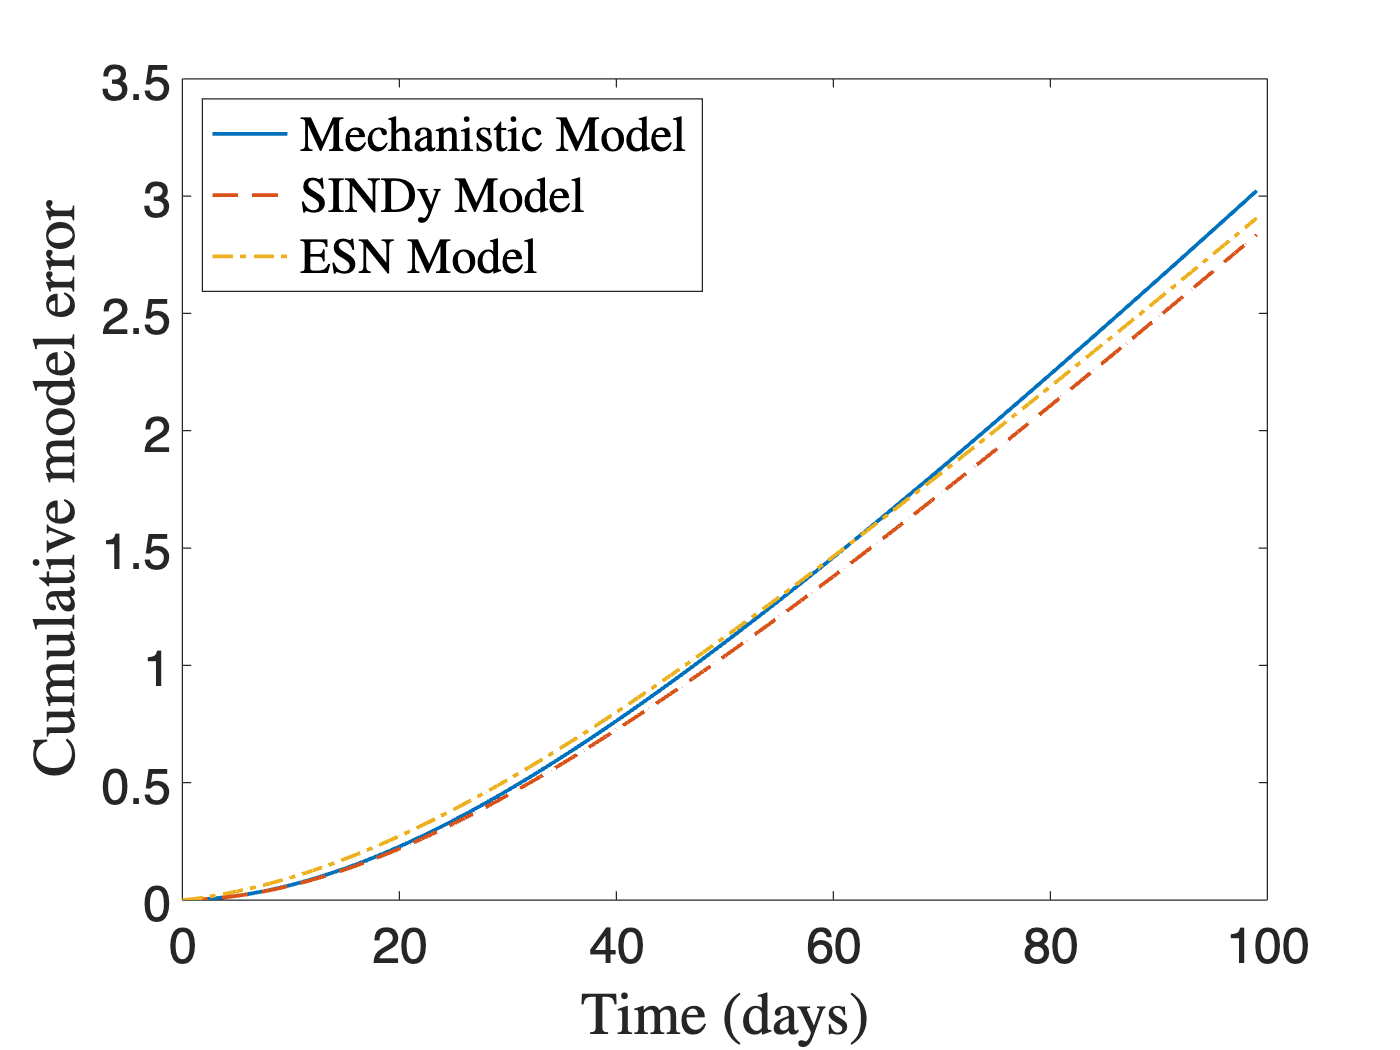

errors = mean(errors, 3);
figure
plot(T, errors(1, :), 'LineWidth', 1.5, 'LineStyle','-')
hold on
plot(T, errors(2, :), 'LineWidth', 1.5, 'LineStyle','--')
plot(T, errors(3, :), 'LineWidth', 1.5, 'LineStyle','-.')
xlabel('Time (days)', 'Interpreter', 'latex', 'FontSize', 20)
ylabel('Cumulative model error', 'Interpreter', 'latex', 'FontSize', 20)
legend('Mechanistic Model', 'SINDy Model', 'ESN Model', 'Interpreter', 'latex', 'FontSize', 20, 'Location', 'Northwest')
ax = gca;
ax.XAxis.FontSize = 20;
ax.YAxis.FontSize = 20;
% ax.YAxis.TickValues = [0 1 2 3 4];
ax.XLabel.FontSize = 24;
ax.YLabel.FontSize = 24;

For completion, an additional plot of the three models evaluated on the empirical precipitation data:

% warmupLen = 100;
% st = 232;
% wst = st - warmupLen;
% intLen = 365;
% mechPrediction = iterateMechanisticModelSimplified(testingN(st), testingR(st:st+intLen-2), xiMech);
% SINDyPrediction = iterateSINDyModel(testingN(st), testingR(st:st+intLen-2), getThetaLib, xiLib);
% x0 = zeros(Dr, 1);
% for dt=0:warmupLen-1
%     u = [testingR(wst+dt); testingN(wst+dt)];
%     x0 = alpha*tanh(Win*u+W*x0) + (1-alpha)*x0;
% end
% [X, esnPrediction] = iterateESN(testingN(st), testingR(st:st+intLen-2), x0, Win, W, Wout, alpha);
% figure
% plot(testingT(st:st+intLen-1), testingN(st:st+intLen-1), 'LineWidth', 1.5, 'LineStyle', '-')
% hold on
% plot(testingT(st:st+intLen-1), mechPrediction, 'LineWidth', 1.5, 'LineStyle', '--')
% plot(testingT(st:st+intLen-1), SINDyPrediction, 'LineWidth', 1.5, 'LineStyle','-.')
% plot(testingT(st:st+intLen-1), esnPrediction, 'LineWidth', 2, 'LineStyle',':')
% xlim([testingT(st) testingT(st+intLen-1)])
% xlabel('Date', 'Interpreter', 'latex', 'FontSize', 20)
% ylabel('NDVI', 'Interpreter', 'latex', 'FontSize', 20)
% legend('Empirical Data','Mechanistic Model', 'SINDy Model', 'ESN Model', 'Interpreter', 'latex', 'FontSize', 20, 'Location', 'Northwest')
% ax = gca;
% ax.XAxis.FontSize = 20;
% ax.YAxis.FontSize = 20;
% ax.XLabel.FontSize = 24;
% ax.YLabel.FontSize = 24;

Also good idea to look at the model predictions for the entire testing set - is this "bad" behaviour representative?

% % calculate model outputs
% warmupLen = 100;
% st = 232;
% wst = st - warmupLen;
% mechPrediction = iterateMechanisticModelSimplified(testingN(st), testingR(st:end-1), xiMech);
% SINDyPrediction = iterateSINDyModel(testingN(st), testingR(st:end-1), getThetaLib, xiLib);
% x0 = zeros(Dr, 1);
% for dt=0:warmupLen-1
%     u = [testingR(wst+dt); testingN(wst+dt)];
%     x0 = alpha*tanh(Win*u+W*x0) + (1-alpha)*x0;
% end
% [X, esnPrediction] = iterateESN(testingN(st), testingR(st:end-1), x0, Win, W, Wout, alpha);

% quintiles = quantile(ndvi, 4);
% figure
% plot(dates, ndvi, 'LineWidth', 1.5, 'LineStyle', '-')
% hold on
% plot(testingT(st:end), mechPrediction, 'LineWidth', 1.5, 'LineStyle', '--')
% plot(testingT(st:end), SINDyPrediction, 'LineWidth', 1.5, 'LineStyle','-.')
% plot(testingT(st:end), esnPrediction, 'LineWidth', 2, 'LineStyle',':')
% plot([dates(1) dates(end)], [quintiles(1) quintiles(1)], 'Color', 'k', 'LineWidth', 1.5, 'LineStyle', '-.')
% xlabel('Date', 'Interpreter','latex', 'FontSize', 20)
% ylabel('NDVI','Interpreter','latex', 'FontSize', 20)
% legend('Processed data', 'Mechanistic model', 'SINDy model', 'ESN model', 'Lowest quintile of processed data', 'Interpreter', 'latex', 'FontSize', 20, 'Location', 'Northwest')
% ax = gca;
% ax.XAxis.FontSize = 20;
% ax.YAxis.FontSize = 20;
% ax.XLabel.FontSize = 24;
% ax.YLabel.FontSize = 24;

## Functions

function Theta = createMechanisticLibrary(N, R, lambda, N0)
% where N and R are column vectors, while lambda, N0 are scalars
    term1 = N.*R./(1+lambda*N);
    term2 = -N.^2;
    term3 = -N./(N0+N);
    Theta = [term1 term2 term3];
end

function N = iterateMechanisticModel(N1, R, lambda, N0, xi)
% where N1 is the initial condition and R is the rainfall, a column vector
    N = zeros(size(R, 1)+1, 1);
    N(1) = N1;
    for t=1:size(R, 1)
        curN = N(t);
        curR = R(t);
        Theta = createMechanisticLibrary(curN, curR, lambda, N0);
        nextN = curN + Theta*xi;
        N(t+1) = nextN;
    end
end

function N = iterateMechanisticModelSimplified(N1, R, xi)
% where N1 is the initial condition and R is the rainfall, a column vector
    N = zeros(size(R, 1)+1, 1);
    N(1) = N1;
    for t=1:size(R, 1)
        curN = N(t);
        curR = R(t);
        Theta = [curR -curN.^2];
        nextN = curN + Theta*xi;
        N(t+1) = nextN;
    end
end

function N = iterateSINDyModel(N1, R, getThetaLib, xi)
% where N1 is the initial condition and R is the rainfall, a column vector
    N = zeros(size(R, 1)+1, 1);
    N(1) = N1;
    for t=1:size(R, 1)
        curN = N(t);
        curR = R(t);
        Theta = getThetaLib(curN, curR);
        nextN = curN + Theta*xi;
        N(t+1) = nextN;
    end
end

function [Win, W] = createReservoir(Din, Dr, sigma, rho, degree)
    Win = 2*sigma*rand(Dr, Din) - sigma;
    W = sprand(Dr,Dr,degree / Dr);
    W = W / abs(eigs(W, 1)) * rho;
end

function [X, Wout] = trainReservoir(U, dotU, Win, W, alpha, beta)
    Dr = size(W, 1);
    n = size(U, 2);
    X = zeros(Dr, n);
    for j=1:n
        if j==1
            xLast = zeros(Dr, 1);
        else
            xLast = X(:,j-1);
        end
        u = U(:,j);
        x = alpha*tanh(Win*u+W*xLast) + (1-alpha)*xLast;
        X(:,j) = x;
    end

    Wout = dotU*X'/(X*X' + beta*eye(Dr));
end

function [X, N] = iterateESN(N1, R, X0, Win, W, Wout, alpha)
    X = zeros(size(X0, 1), size(R, 1) + 1);
    X(:, 1) = X0;
    N = zeros(size(R, 1) + 1, 1);
    N(1) = N1;
    for t=1:size(R, 1)
        xLast = X(:, t);
        NLast = N(t);
        RLast = R(t);
        u = [RLast; NLast];
        x = alpha*tanh(Win*u + W*xLast) + (1-alpha)*xLast;
        y = Wout*x;
        X(:, t+1) = x;
        N(t+1) = NLast + y;
    end
end